# Explore and Analyze Storm Events

Explore the **frequency** of various storm events and locations and the associated **damage costs**. We are not using the timestamps for analysis, so we can convert the data to a table.

clear;
load prepEvents
data = timetable2table(data);
head(data)

ans = 8×18 table
            Time             event_id         state            event_type        damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon                                                                                             event_narrative                                                                                             storm_duration    begin_day    end_day    year      end_timestamp       damage_total       weathercats   
    ____________________    __________    ______________    _________________    _______________    ____________

A **heatmap** (2017a) visualization is helpful in exploring patterns across categories like the events and locations. Colors on the heatmap represent values which can be used to help identify patterns for further exploration.

Visualize the **number of events per state** using the [`heatmap`](http://www.mathworks.com/help/matlab/ref/heatmap.html) function. Create a large figure with a helper function (see bottom of this script) since there are a number of states and events.

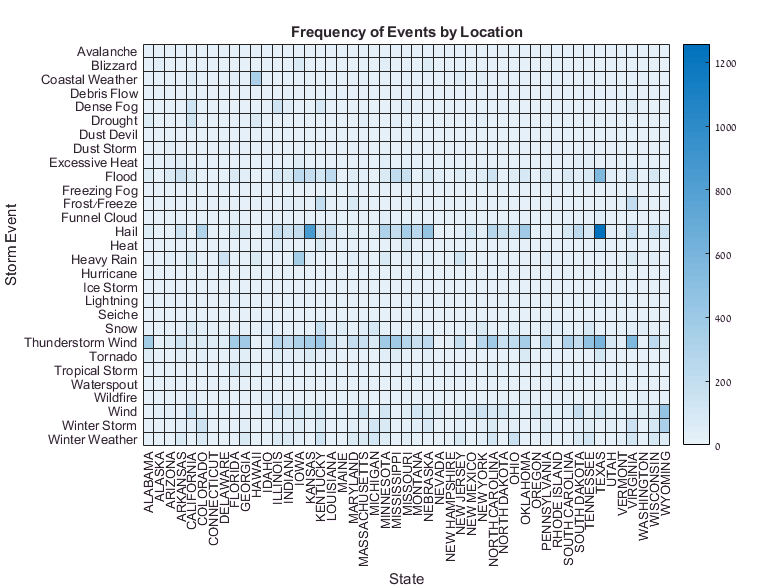

bigFigure;
heatmap(data,'state','weathercats'); % see Hail in Texas ans Kansas
xlabel('State')
ylabel('Storm Event')
title('Frequency of Events by Location')

The visualization shows several patterns. For example, some states experience significantly more hail than others (like Texas and Kansas) and most states experience thunderstorm wind. 

**Do certain states experience high damage costs because of these events?** Do some events tend to cost more than others?

We can visualize the **average cost of events** by state with a heatmap by specifying the damage variable to use as the **color**. The default method to determine color is the **mean** when passing the `ColorVariable`. The calculation method used can also be adjusted through Name - Value pairs (count, mean, median, sum, none). The colormap and other visual properties can also be adjusted further.

bigFigure;
h = heatmap(data,'state','weathercats',...
    'ColorVariable','damage_total');
h.Colormap = hot;
title('Mean Damage Cost of Events by Location')
xlabel('State')
ylabel('Storm Event')

The low values and missing values (`NaN`) might be difficult to distinguish with this colormap since the default value for missing data is dark gray. Adjust the color to a lighter shade of gray.

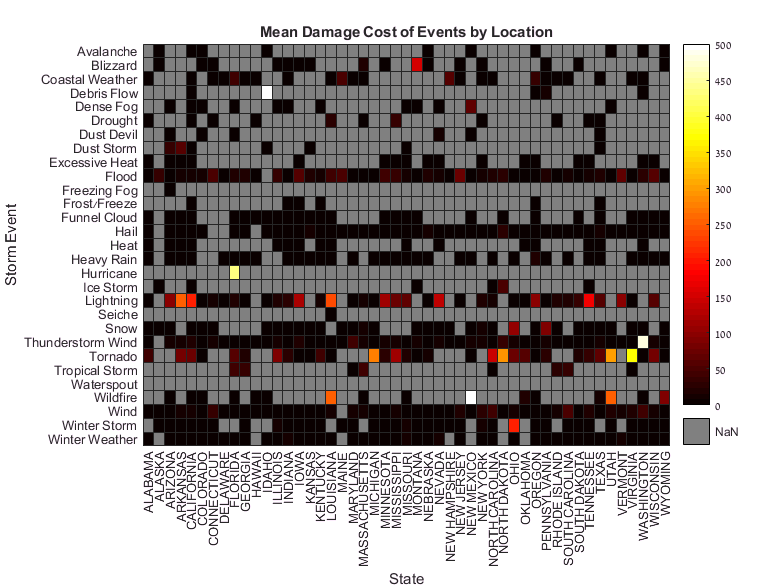

h.MissingDataColor = [0.5 0.5 0.5];

There are several events which clearly are more expensive than others (debris flow in Idaho, wildfires in New Mexico, hurricanes in Florida). Also, **lightning and tornadoes are costly events** which occur in multiple states. 

The calculated mean values can be accessed from the heatmap output, `h`, but we also want additional statistical measures. There are a several ways to perform grouped calculations like the mean on table variables. The `grpstats` function is useful in this case since we are looking for **summary statistics **(other functions like `findgroups` and `splitapply` and `varfun` are general purpose).

Find the **mean, standard deviation and the confidence interval **around the mean for **each weather event** using `grpstats`.

damageByEvent = grpstats(data,'weathercats',...
    {'mean','std','meanci'},'DataVars','damage_total');
damageByEvent = sortrows(damageByEvent,'mean_damage_total','descend')

damageByEvent = 29×5 table
                            weathercats       GroupCount    mean_damage_total    std_damage_total     meanci_damage_total  
                         _________________    __________    _________________    ________________    ______________________

    Hurricane            Hurricane              10            436.5              284.58                 198.59       674.41
    Lightning            Lightning             256           56.682              168.47                 34.889       78.475
    Tornado              Tornado               821           55.042              140.35                 44.265       65.818
    Tropical Storm       Tropical Storm        204           30.604              112.88                 13.411    

Visualize the **distributions of the damage** caused by various events with a [boxplot](http://www.mathworks.com/help/stats/boxplot.html). Changing the `PlotStyle` to compact can help when visualizing many categories.

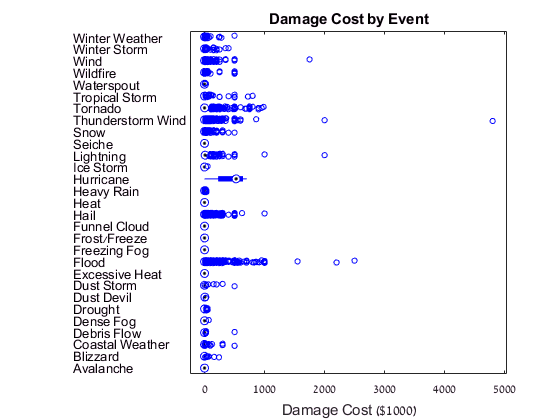

figure
boxplot(data.damage_total,data.weathercats,...
    'PlotStyle','compact','Orientation','horizontal')
xlabel('Damage Cost ($1000)')
title('Damage Cost by Event')

Lightning and tornadoes are some of the more costly events when it comes to damage. The boxplot also shows a number of values near zero, some with many outliers and a large spread, so these additional considerations may be necessary in future modeling tasks.

Visualize storm event information on a map

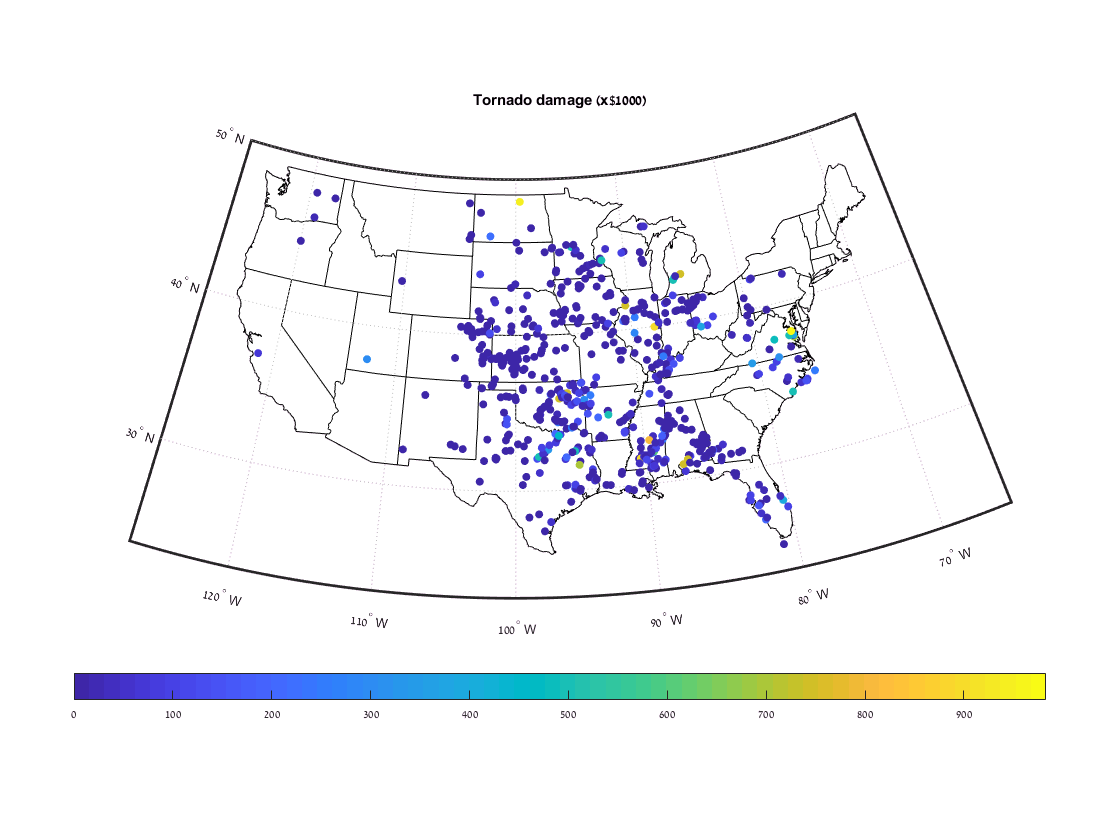

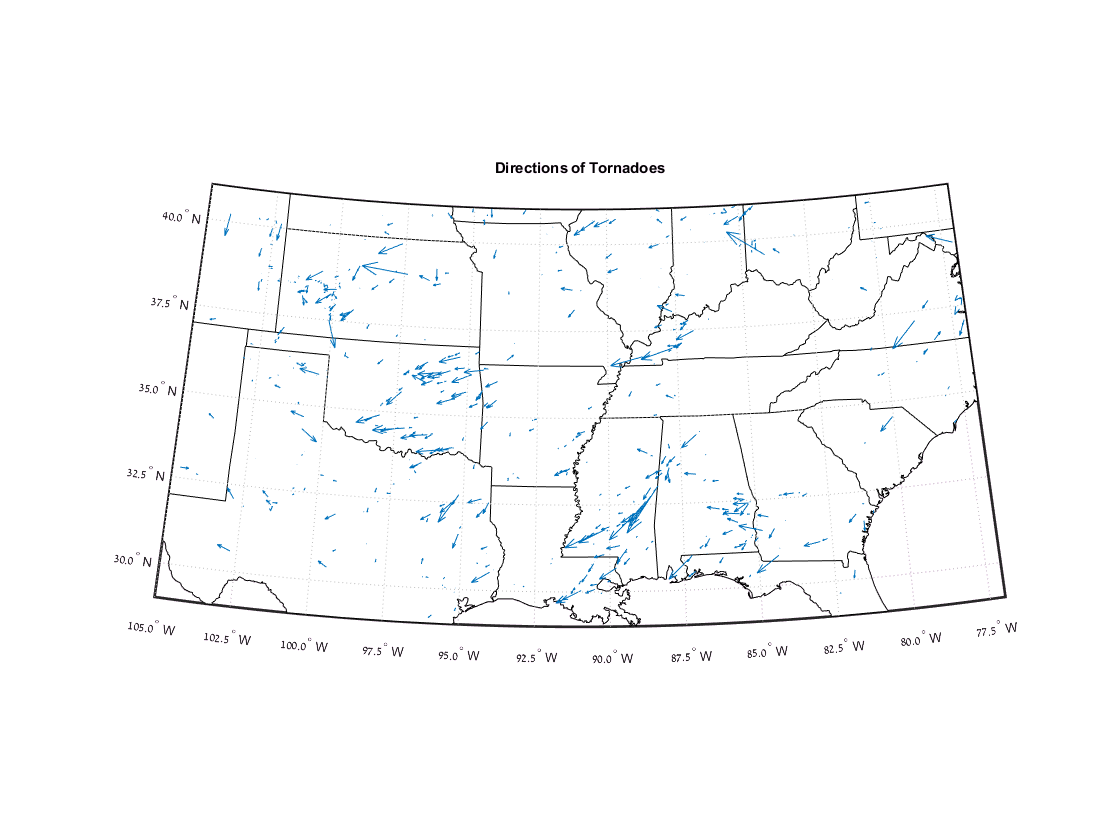

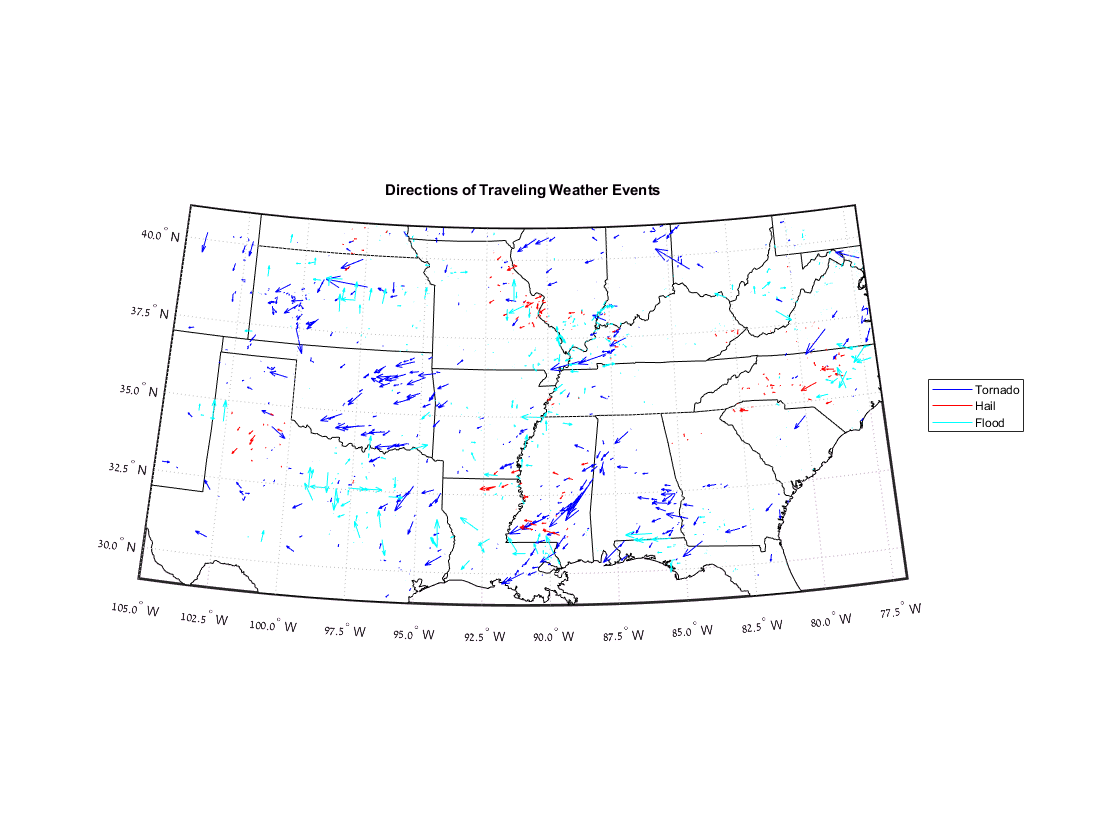

visualizeByLocation  

## Helper Funs

function f = bigFigure
    f = figure;
    f.Position = f.Position.*[1 1 1.4 1.4];
end 